# 1. For both ECE 4850 and ECE 7650: Implement a Backpropagation ANN to solve the NXOR problem: Use the following data set:

%% Pre-amble
import neural_network.*

%% Import targets and features
x = [0,0; 0,1; 1,0; 1,1];
y = [1;0;0;1];

## Create a (3,4,1) architecture: use two input neurons and one bias, three hidden neurons and one bias, and one output neuron, i.e., (3,4,1).

% object = neural_network(input_layer,hidden_neuron,features,target,...
% learning_rate,max_epochs,Logistic=false,TestingSet=false)
obj = neural_network(2,3,x,y,10,5000,false,false);

## (1 mark) Derive the forward and backward propagation equations for this architecture in a manner similar to that done in the lecture slides for the (3,3,1) architecture.

[error,final_weights,final_activations] = gradient_descent(obj);

Epoch 500: Error is: 2.067342e-02 
Correct # of assignments this batch: 36 /500 
Epoch 1000: Error is: 2.206930e-03 
Correct # of assignments this batch: 128 /500 
Epoch 1500: Error is: 1.615320e-04 
Correct # of assignments this batch: 384 /500 
Epoch 2000: Error is: 3.811883e-04 
Correct # of assignments this batch: 500 /500 
Neural Network Training Complete! 

Final Error Is: 3.270481e-04 


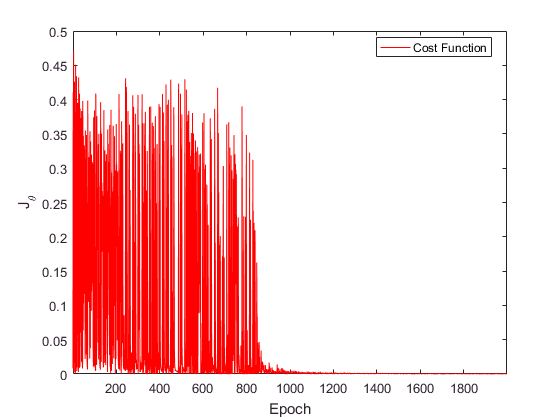

plot_graph(obj,error);

## (2 marks) Test your implementation for correctness by computing the weights using pencil, paper, and calculator calculations for the 1st iteration of the algorithm (show your work), and compare your hand calculations with the weights obtained after the 1st iteration of your code. Use the training example {1 0 0}. Randomize your weights between the range {-1 to +1}. Submit your hand calculations and the Matlab code for the 1st iteration, including the value of each randomized weight, and the value of each weight after the 1st iteration.

%% Set testing to true to initialize test parameters. This are set to the same
%% as the worked out example on paper

obj = neural_network(2,3,x,y,0.1,1,false,true);
[error,final_weights,final_activations] = gradient_descent(obj);

Epoch  1: Error is: 2.334439e-01 
Correct # of assignments this batch: 0 /1.000000e-01 


display('Final Weights after 1 iteration:');

Final Weights after 1 iteration:


final_weights{1} % First layer

ans =          0   -1.0037    0.0029
    0.5000    1.0000    1.0000


final_weights{2} % Second layer

ans =    -0.0108
    0.9926
   -1.0108



%% See "worked_out_example.docx" for worked out example

## (3 marks) After a sufficient number of epochs are run to obtain 100% correct classification, examine and analyze the activations of the hidden layer, to determine the nature of the extracted features. Give a truth table similar to that shown in the lecture notes to show the nature of the extracted features. Are the extracted features the same as that given in the lecture notes? Discuss. Can you suggest a way to run the algorithm so that it will produce the same features as those given in the lecture notes? If so test and verify it. Submit your Matlab code, the final value of the weights, and a description of the extracted features to the TA for marking.

obj = neural_network(2,3,x,y,8,5000,false,false);
[error,final_weights,final_activations,random_set] = gradient_descent(obj);

Epoch 500: Error is: 1.589803e-01 
Correct # of assignments this batch: 34 /500 
Epoch 1000: Error is: 1.034434e-03 
Correct # of assignments this batch: 139 /500 
Epoch 1500: Error is: 4.086107e-04 
Correct # of assignments this batch: 427 /500 
Epoch 2000: Error is: 7.122022e-05 
Correct # of assignments this batch: 500 /500 
Neural Network Training Complete! 

Final Error Is: 2.307306e-04 


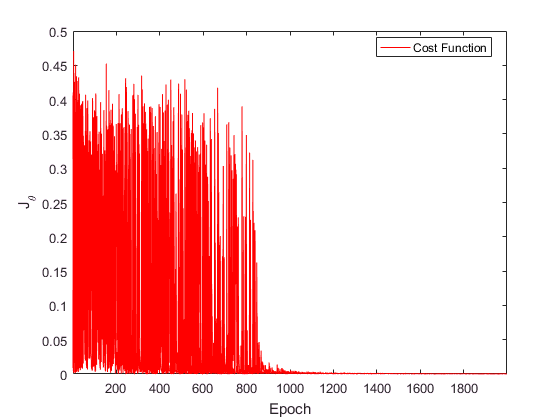

plot_graph(obj,error);

format short

Last 5 activations (These are in the order a1, a2, a3, a4 (target))

final_activations(~any(final_activations,2),:) = [];
final_activations(end-4:end,:)

ans =     0.0144    0.0196    0.0000    0.9660
    0.3359    0.5507    0.9078    0.9883
    0.0006    0.9212    0.0056    0.0218
    0.9268    0.0021    0.0108    0.0215
    0.0006    0.9215    0.0056    0.0215


Last 5 randomized samples (These are in the order x1, x2, y(target))

random_set(~any(random_set,2),:) = [];
random_set(end-4:end,:)

ans =      1     1     1
     0     0     1
     1     0     0
     0     1     0
     1     0     0


%% See "worked_out_example.docx" for explanation and truth table

## For ECE 7650 students only: Given the equation. Run your Matlab code using the logistic cost function and compare the results with that obtained using the Euclidean cost function as done in (1) above. Submit your solutions to me for marking.

obj = neural_network(2,3,x,y,1,5000,true,false); %Set Logistic=True
[error,final_weights,final_activations,random_set] = gradient_descent(obj);

Epoch 500: Error is: 2.699480e-01 
Correct # of assignments this batch: 4 /500 
Epoch 1000: Error is: 1.173854e-01 
Correct # of assignments this batch: 89 /500 
Epoch 1500: Error is: 1.291372e-02 
Correct # of assignments this batch: 381 /500 
Epoch 2000: Error is: 5.623902e-03 
Correct # of assignments this batch: 500 /500 
Neural Network Training Complete! 

Final Error Is: 5.757911e-03 


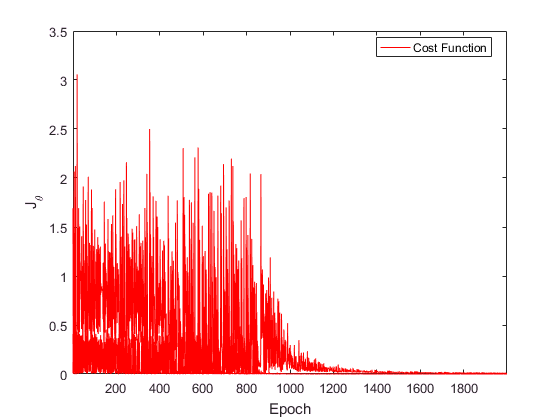

plot_graph(obj,error);

%% See "worked_out_example.docx" for explanation